# Pairing assessment

## Import datasets

Obtained from the *2.0-ara-pairing-II.ipynb* notebook.

Open the CSV file on Microsoft's Excel and save it as a XLSX file.

% Dataset curated and rules 90 min
% Columns: SUBJECT_ID, HADM_ID, ICUSTAY_ID, ICU_ADMISSIONTIME, ICU_DISCHARGETIME, 
% LOS_ICU_days, first_ICU_stay, TIMER, STARTTIME, GLCTIMER, ENDTIME, INPUT, 
% INPUT_HRS, INSULINTYPE, EVENT, GLC, GLCSOURCE, INFXSTOP, GLC_AL, GLCTIMER_AL,
% GLCSOURCE_AL, RULE, Repeated
BolusesCUR90 = importfile_BOLcur("BolusesCUR.xlsx", "BolusesCUR", [2, 88465]);

% Dataset curated and rules 60 min
% Columns: SUBJECT_ID, HADM_ID, ICUSTAY_ID, ICU_ADMISSIONTIME, ICU_DISCHARGETIME, 
% LOS_ICU_days, first_ICU_stay, TIMER, STARTTIME, GLCTIMER, ENDTIME, INPUT, 
% INPUT_HRS, INSULINTYPE, EVENT, GLC, GLCSOURCE, INFXSTOP, GLC_AL, GLCTIMER_AL, 
% GLCSOURCE_AL, RULE, Repeated
BolusesCUR60 = importfile_bolus_cur_60("BolusesCUR_60.xlsx", "BolusesCUR_60", [2, 88465]);

% Dataset curated with no rules
% Columns: SUBJECT_ID, HADM_ID, ICUSTAY_ID, ICU_ADMISSIONTIME, ICU_DISCHARGETIME,
% LOS_ICU_days, first_ICU_stay, TIMER, STARTTIME, GLCTIMER, ENDTIME, INPUT, 
% INPUT_HRS, INSULINTYPE, EVENT, GLC, GLCSOURCE, INFXSTOP, GLC_AL, GLCTIMER_AL, 
% GLCSOURCE_AL, RULE, Repeated
BolusesCURnr = importfile_bolus_cur_nr("BolusesCUR_nr.xlsx", "BolusesCUR_nr", [2, 88465]);

## Select one entry per ICU stay in each method

% Select first reading per method

uniqueICU = unique(BolusesCUR90.ICUSTAY_ID);

first_readings = array2table(nan(length(uniqueICU),18));
first_readings.Properties.VariableNames = {'ICUSTAY_ID',...
    'ICU_ADMISSIONTIME','ICU_DISCHARGETIME','LOS_min'...
    'STARTTIME','INPUT',...
    'GLC_AL90','GLCTIMER_AL90','GLCSOURCE_AL90','RULE90',...
    'GLC_AL60','GLCTIMER_AL60','GLCSOURCE_AL60','RULE60',...
    'GLC_ALnr','GLCTIMER_ALnr','GLCSOURCE_ALnr','RULEnr'};

for i=1:length(uniqueICU)
    ICUstay = uniqueICU(i);
    idx_nr = BolusesCURnr.ICUSTAY_ID == ICUstay;
    idx_90 = BolusesCUR90.ICUSTAY_ID == ICUstay;
    idx_60 = BolusesCUR60.ICUSTAY_ID == ICUstay;
    
    % ICU stay
    first_readings(i,'ICUSTAY_ID') = array2table(ICUstay);
    
    tbl_90 = BolusesCUR90(idx_90,:);
    tbl_90 = tbl_90(~any(ismissing(tbl_90,nan),2),:);
    
    tbl_60 = BolusesCUR60(idx_60,:);
    tbl_60 = tbl_60(~any(ismissing(tbl_60,nan),2),:);
    
    tbl_nr = BolusesCURnr(idx_nr,:);
    %tbl_nr = tbl_nr(~any(ismissing(tbl_nr,nan),2),:);
    
    % First insulin input
    insulin_row = topkrows(tbl_nr,1,{'STARTTIME'},'ascend');
    
    % Admission and discharge time
    first_readings(i, 'ICU_ADMISSIONTIME') = array2table(datenum(insulin_row.ICU_ADMISSIONTIME));
    
    % Discharge time
    first_readings(i,'ICU_DISCHARGETIME') = array2table(datenum(insulin_row.ICU_DISCHARGETIME));
    
    % Estimate LOS
    t1=table2array(insulin_row(:,{'ICU_DISCHARGETIME'}));
    t2=table2array(insulin_row(:,{'ICU_ADMISSIONTIME'}));
    dt_min=array2table(duration(time(between(t2,t1,'time')),'Format','m'), ...
        "VariableNames",{'LOS_min'});
    first_readings(i,'LOS_min') = array2table(minutes(dt_min.LOS_min));
    
    % Insulin
    first_readings(i,'STARTTIME') = array2table(datenum(insulin_row.STARTTIME));
    first_readings(i,"INPUT") = insulin_row(:,'INPUT');
    
    % No rules glucose data
    first_readings(i,"GLC_ALnr") = insulin_row(:,'GLC_AL');
    first_readings(i,"GLCSOURCE_ALnr") = insulin_row(:,"GLCSOURCE_AL");
    first_readings(i,'GLCTIMER_ALnr') = array2table(datenum(insulin_row.GLCTIMER_AL));
    first_readings(i,'RULEnr') = insulin_row(:,'RULE');
    
    % Indexes of i insulin input on tbl_60 and tbl_90
    idx_i90 = tbl_90.STARTTIME == insulin_row.STARTTIME;
    idx_i60 = tbl_60.STARTTIME == insulin_row.STARTTIME;
    
    if ~isempty(tbl_90(idx_i90,:))
        % 90 min
        if sum(idx_i90)>=2
            first_readings(i,"GLC_AL90") = tbl_90(find(idx_i90, 1 ),"GLC_AL");
            first_readings(i,"GLCSOURCE_AL90") = tbl_90(find(idx_i90, 1 ),'GLCSOURCE_AL');
            first_readings(i,'GLCTIMER_AL90') = array2table(datenum(table2array(tbl_90(find(idx_i90, 1 ),'GLCTIMER_AL'))));
            first_readings(i,'RULE90') = tbl_90(find(idx_i90, 1 ), 'RULE');
        else
            first_readings(i,"GLC_AL90") = tbl_90(idx_i90,'GLC_AL');
            first_readings(i,"GLCSOURCE_AL90") = tbl_90(idx_i90,'GLCSOURCE_AL');
            first_readings(i,'GLCTIMER_AL90') = array2table(datenum(table2array(tbl_90(idx_i90,'GLCTIMER_AL'))));
            first_readings(i,'RULE90') = tbl_90(idx_i90,'RULE');
        end
    else
        first_readings(i,"GLC_AL90") = array2table(nan);
    end
    
    if ~isempty(tbl_90(idx_i60,:))
        % 60 min
        if sum(idx_i60)>=2
            first_readings(i,"GLC_AL60") = tbl_60(find(idx_i60, 1 ),"GLC_AL");
            first_readings(i,"GLCSOURCE_AL60") = tbl_60(find(idx_i60, 1 ),'GLCSOURCE_AL');
            first_readings(i,'GLCTIMER_AL60') = array2table(datenum(table2array(tbl_60(find(idx_i60, 1 ),'GLCTIMER_AL'))));
            first_readings(i,'RULE60') = tbl_60(find(idx_i60, 1 ), 'RULE');
        else
            first_readings(i,"GLC_AL60") = tbl_60(idx_i60,'GLC_AL');
            first_readings(i,"GLCSOURCE_AL60") = tbl_60(idx_i60,'GLCSOURCE_AL');
            first_readings(i,"GLCTIMER_AL60") = array2table(datenum(table2array(tbl_60(idx_i60,'GLCTIMER_AL'))));
            first_readings(i,"RULE60") = tbl_60(idx_i60,'RULE');
        end
    else
        first_readings(i,"GLC_AL60") = array2table(nan);
    end
end

### Estimate differences between Insulin timestamp and Glucose timestamp

first_readings = sortrows(first_readings,'INPUT','ascend');

first_readings(:,'dt_nr') = array2table(abs(datetime(table2array(first_readings(:,'STARTTIME')),'ConvertFrom','datenum') - ...
    datetime(table2array(first_readings(:,'GLCTIMER_ALnr')),'ConvertFrom','datenum')));
disp(['\Delta time insulin - glucose reading (no rules)',newline,...
    'Mean: ',num2str(minutes(mean(first_readings.dt_nr,'omitnan')),'%0.2f'),' +/- ',...
    num2str(minutes(std(first_readings.dt_nr,'omitnan')),'%0.2f'),' min']);

\Delta time insulin - glucose reading (no rules)
Mean: 86.58 +/- 362.15 min


first_readings(:,'dt_90') = array2table(abs(datetime(table2array(first_readings(:,'STARTTIME')),'ConvertFrom','datenum') - ...
    datetime(table2array(first_readings(:,'GLCTIMER_AL90')),'ConvertFrom','datenum')));
disp(['\Delta time insulin - glucose reading (90 min)',newline,...
    'Mean: ',num2str(minutes(mean(first_readings.dt_90,'omitnan')),'%0.2f'),...
    ' +/- ',num2str(minutes(std(first_readings.dt_90,'omitnan')),'%0.2f'),' min']);

\Delta time insulin - glucose reading (90 min)
Mean: 26.75 +/- 23.16 min


first_readings(:,'dt_60') = array2table(abs(datetime(table2array(first_readings(:,'STARTTIME')),'ConvertFrom','datenum') - ...
    datetime(table2array(first_readings(:,'GLCTIMER_AL60')),'ConvertFrom','datenum')));
disp(['\Delta time insulin - glucose reading (60 min)',newline,...
    'Mean: ',num2str(minutes(mean(first_readings.dt_60,'omitnan')),'%0.2f'),...
    ' +/- ',num2str(minutes(std(first_readings.dt_60,'omitnan')),'%0.2f'),' min']);

\Delta time insulin - glucose reading (60 min)
Mean: 22.01 +/- 18.02 min


### $\Delta$glucose 90 minutes

first_readings(:,'dg_90') = array2table(abs(first_readings.GLC_ALnr - first_readings.GLC_AL90));
first_readings(isnan(first_readings.dg_90),'dg_90') = first_readings(isnan(first_readings.dg_90),'GLC_ALnr');
first_readings(isnan(first_readings.dg_90),"dg_90") = first_readings(isnan(first_readings.dg_90),'GLC_AL90');

disp(['Paired glucose (90 min)',newline,'Mean: ',num2str(mean(first_readings.GLC_AL90,'omitnan'),'%0.2f'),...
    ' +/- ',num2str(std(first_readings.GLC_AL90,'omitnan'),'%0.2f'),' mg/dL']);

Paired glucose (90 min)
Mean: 192.51 +/- 66.07 mg/dL


disp(['\Delta glucose 90 min - no rules',newline,'Mean: ',...
    num2str(mean(first_readings.dg_90,'omitnan'),'%0.2f'),...
    ' +/- ',num2str(std(first_readings.dg_90,'omitnan'),'%0.2f'),...
    ' mg/dL',newline,'NO paired in both scenarios: ',...
    num2str(sum(isnan(first_readings.dg_90)))]);

\Delta glucose 90 min - no rules
Mean: 26.25 +/- 62.57 mg/dL
NO paired in both scenarios: 861


### $\Delta$glucose 60 minutes

first_readings(:,'dg_60') = array2table(abs(first_readings.GLC_ALnr - first_readings.GLC_AL60));
first_readings(isnan(first_readings.dg_60),'dg_60') = first_readings(isnan(first_readings.dg_60),'GLC_ALnr');
first_readings(isnan(first_readings.dg_60),"dg_60") = first_readings(isnan(first_readings.dg_60),'GLC_AL60');

disp(['Paired glucose (60 min)',newline,...
    'Mean: ',num2str(mean(first_readings.GLC_AL60,'omitnan'),'%0.2f'),...
    ' +/- ',num2str(std(first_readings.GLC_AL60,'omitnan'),'%0.2f'),' min']);

Paired glucose (60 min)
Mean: 191.51 +/- 65.40 min


disp(['\Delta glucose 60 min - no rules',newline,'Mean: ',...
    num2str(mean(first_readings.dg_60,'omitnan'),'%0.2f'),...
    ' +/- ',num2str(std(first_readings.dg_60,'omitnan'),'%0.2f'),...
    ' mg/dL', newline,...
    'NO paired in both scenarios: ', num2str(sum(isnan(first_readings.dg_60)))]);

\Delta glucose 60 min - no rules
Mean: 43.72 +/- 81.57 mg/dL
NO paired in both scenarios: 877


### Paired glucose  - no rules

disp(['Paired glucose (no rules)',newline,'Mean: ',num2str(mean(first_readings.GLC_ALnr,'omitnan'),'%0.2f'),...
    ' +/- ',num2str(std(first_readings.GLC_ALnr,'omitnan'),'%0.2f'),' mg/dL']);

Paired glucose (no rules)
Mean: 186.85 +/- 65.29 mg/dL


**Histograms of time gaps between glucoe reading and insulin event**

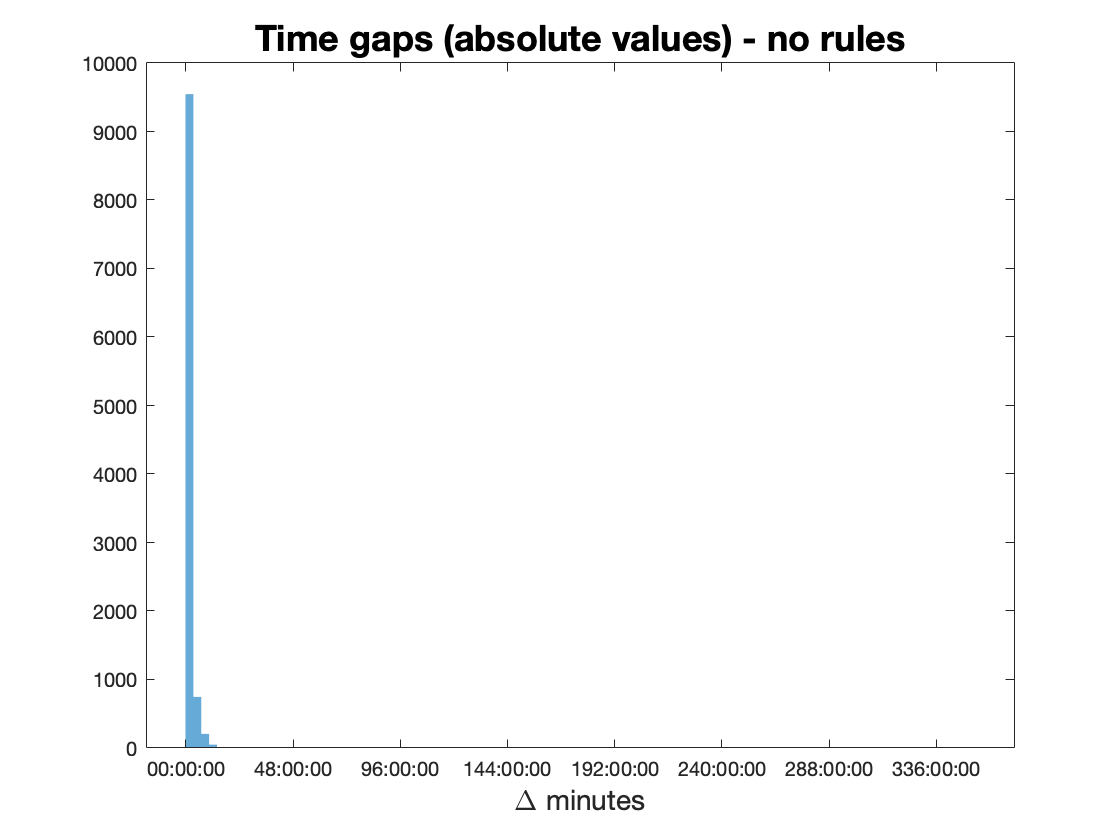

histogram(first_readings.dt_nr,100,'EdgeAlpha',0);
title('Time gaps (absolute values) - no rules','FontSize',18)
xlabel('\Delta minutes', 'FontSize',14)

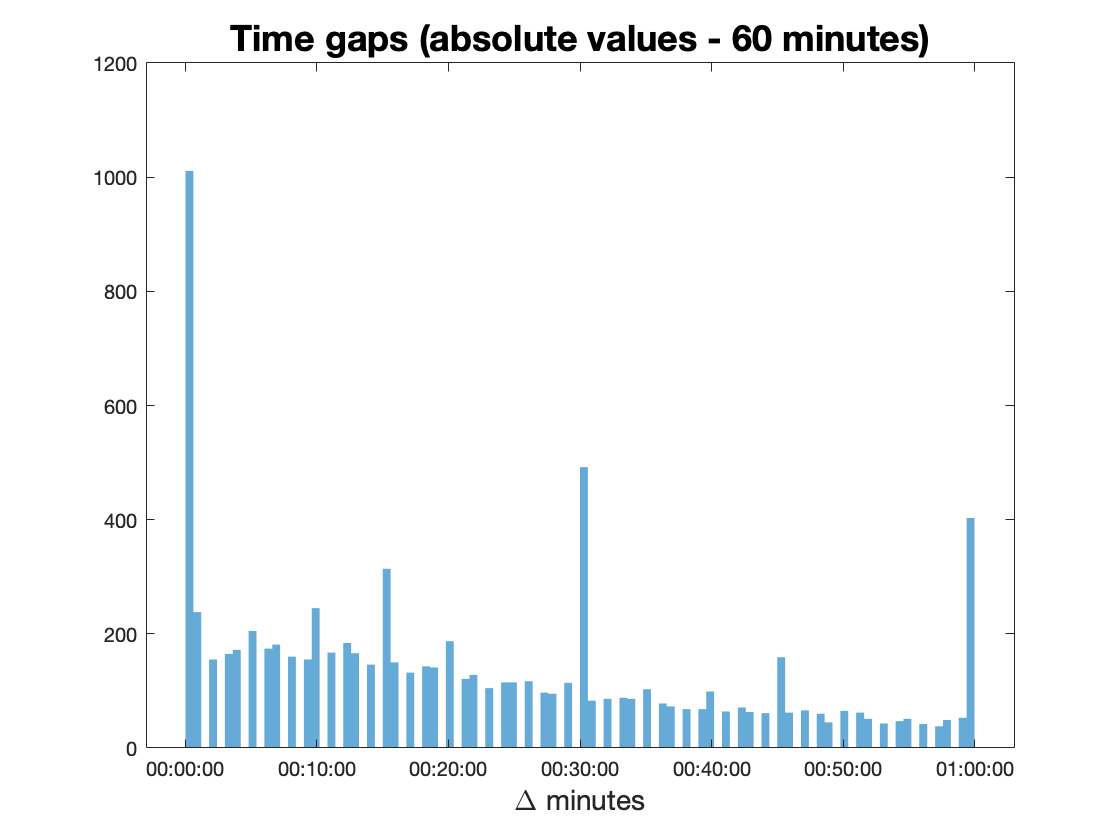

histogram(first_readings.dt_60,100,'EdgeAlpha',0);
title('Time gaps (absolute values - 60 minutes)','FontSize',18)
xlabel('\Delta minutes', 'FontSize',14)

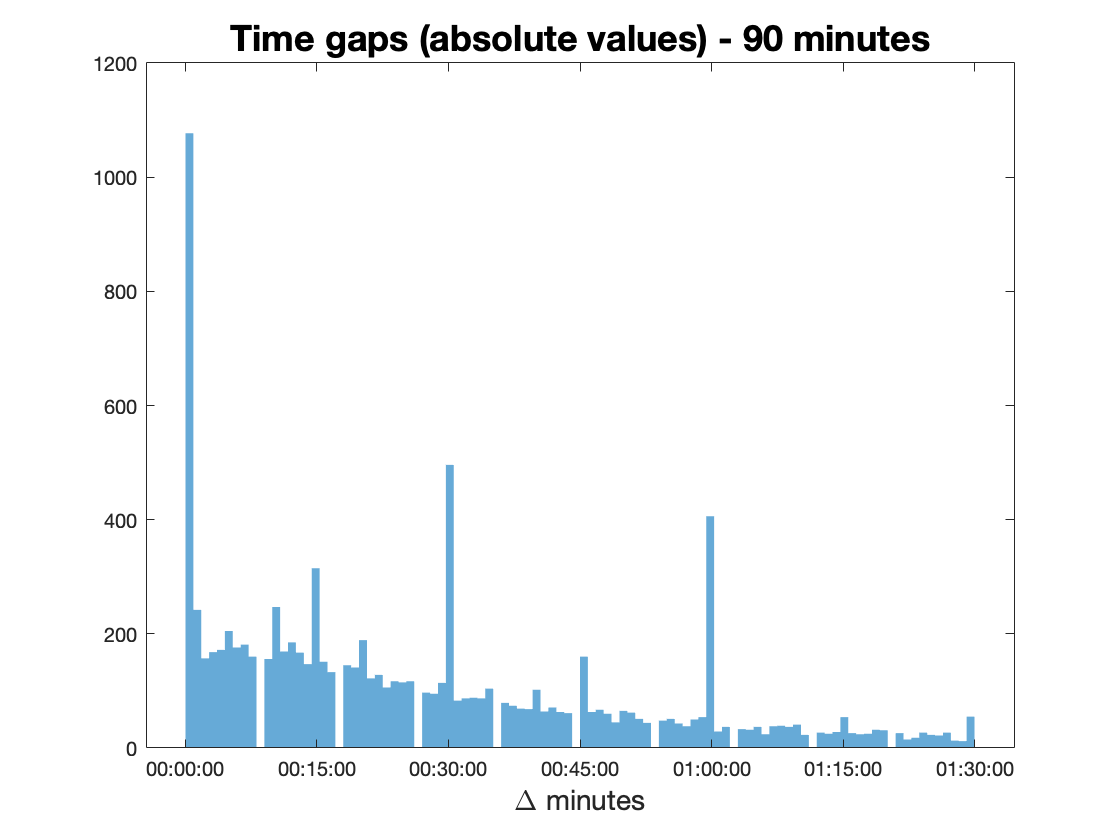

histogram(first_readings.dt_90,100,'EdgeAlpha',0);
title('Time gaps (absolute values) - 90 minutes','FontSize',18)
xlabel('\Delta minutes', 'FontSize',14)

## Hypothesis testing

**Wilcoxon Signed Rank Test**

It is a nonparametric test for two populations when the observations are paired. In this case, the test statistic, `W`, is the sum of the ranks of positive differences between the observations in the two samples (that is, `x`* – *`y`). When you use the test for one sample, then `W` is the sum of the ranks of positive differences between the observations and the hypothesized median value $M_0$.

% Replace missing values in dt_nr for values in dt_90
% Values that were not paired with no rules
first_readings(:,'A') = first_readings(:,'dt_nr');
first_readings(isnan(first_readings.dt_nr),'A') = first_readings(isnan(first_readings.dt_nr),'dt_90');
disp(['Values that were not paired with no rules but paired in scenario A: ', ...
    num2str(sum(table2array(first_readings(isnan(first_readings.dt_nr),'dt_90'))>0))])

Values that were not paired with no rules but paired in scenario A: 24


% Replace missing values in dt_nr for values in dt_60
% Values that were not paired with no rules
first_readings(:,'B') = first_readings(:,'dt_nr');
first_readings(isnan(first_readings.dt_nr),'B') = first_readings(isnan(first_readings.dt_nr),'dt_60');
disp(['Values that were not paired with no rules but paired in scenario B: ', ...
    num2str(sum(table2array(first_readings(isnan(first_readings.dt_nr),'dt_60'))>0))])

Values that were not paired with no rules but paired in scenario B: 17


% Difference only between glucose readings
% Whole array
[h,p,~,stats] = ttest(table2array(first_readings(~isnan(first_readings.dg_90),'dg_90')));
disp(['[Glucose fingerstick] - [Glucose serum]',newline,'Rejects Ho at the 5% significance level: ', ...
    num2str(h),', p-value = ', num2str(p,'%0.2e'),', t statistic = ', num2str(stats.tstat,'%0.2f')])

[Glucose fingerstick] - [Glucose serum]
Rejects Ho at the 5% significance level: 1, p-value = 0.00e+00, t statistic = 43.24


### Time windows for scenario A

% 90 minutes
theta_array = [30 60 90 120];

CIdata = nan(5,length(theta_array)+1);

d_glc = first_readings.dg_90;

for i=1:(length(theta_array)+1)
    if i==1
        theta1 = minutes(0);
        theta2 = minutes(theta_array(i));
    else
        if i==(length(theta_array)+1)
            theta1 = minutes(theta_array(i-1));
            theta2 = minutes(max(first_readings.A)+minutes(1));
        else
            theta1 = minutes(theta_array(i-1));
            theta2 = minutes(theta_array(i));
        end
    end
    theta = ((first_readings.A)>=theta1)&((first_readings.A)<theta2);
    
    % Paired Wilcoxon rank test
    % Within +/- theta min
    [p,h,stats] = signrank(d_glc(theta));
    disp('Wilcoxon rank test')
    disp(['[Glucose nr] - [Glucose 90] within ',...
        char(theta1),'-',char(theta2),' min',newline,...
        'Rejects Ho at the 5% significance level: ', ...
        num2str(h),newline,'p-value = ', num2str(p,'%0.2e'),...
        ', W statistic = ', num2str(stats.signedrank,'%0.2f'), newline])
    disp(['Mean: ',num2str(mean(d_glc(theta)),...
        '%0.2f'),' +/- ',...
        num2str(std(d_glc(theta)),...
        '%0.2f'),newline]);
    disp(['Median: ', num2str(median(d_glc(theta)))]);
    disp(['Q1: ', num2str(quantile(d_glc(theta),0.25)), ...
        newline, ...
        'Q3: ', num2str(quantile(d_glc(theta),0.75)),newline]);
    N = length(d_glc(theta));
    disp(['Entries for ',char(theta1),'-',char(theta2),': ', ...
        num2str(N),newline,...
        num2str((N/(length(d_glc))*100),2),...
        '% of total entries',newline,' '])
    
    % Compute ‘Standard Error Of The Mean’ Of 
    % All Experiments At Each time gap
    ySEM = std(d_glc(theta))/sqrt(N);
    
    % Calculate 95% Probability Intervals Of 
    % t-Distribution
    CI95 = tinv([0.025 0.975], N-1);
    
    % Calculate 95% Confidence Intervals Of 
    % All Experiments At Each time gap
    yCI95 = bsxfun(@times, ySEM, CI95(:));
    
    % Allocate data
    CIdata(1:2,i) = yCI95;
    % Mean
    CIdata(3,i) = mean(d_glc(theta));
    % SD
    CIdata(4,i) = std(d_glc(theta));
    % N
    CIdata(5,i) = N;
end

Wilcoxon rank test


[Glucose nr] - [Glucose 90] within 0 min-30 min min
Rejects Ho at the 5% significance level: 1
p-value = 1.15e-28, W statistic = 13530.00



Mean: 2.17 +/- 16.77



Median: 0


Q1: 0
Q3: 0



Entries for 0 min-30 min: 4468
39% of total entries
 


Wilcoxon rank test


[Glucose nr] - [Glucose 90] within 30 min-60 min min
Rejects Ho at the 5% significance level: 1
p-value = 3.93e-31, W statistic = 16110.00



Mean: 2.36 +/- 13.48



Median: 0


Q1: 0
Q3: 0



Entries for 30 min-60 min: 2548
22% of total entries
 


Wilcoxon rank test


[Glucose nr] - [Glucose 90] within 60 min-90 min min
Rejects Ho at the 5% significance level: 1
p-value = 1.19e-29, W statistic = 14535.00



Mean: 4.46 +/- 16.58



Median: 0


Q1: 0
Q3: 0



Entries for 60 min-90 min: 1313
11% of total entries
 


Wilcoxon rank test


[Glucose nr] - [Glucose 90] within 90 min-120 min min
Rejects Ho at the 5% significance level: 1
p-value = 4.11e-76, W statistic = 103285.00



Mean: 143.45 +/- 97.15



Median: 157.5


Q1: 44
Q3: 195



Entries for 90 min-120 min: 502
4.4% of total entries
 


Wilcoxon rank test


[Glucose nr] - [Glucose 90] within 120 min-劸 min
Rejects Ho at the 5% significance level: 1
p-value = 3.36e-292, W statistic = 1583310.00



Mean: 103.39 +/- 83.72



Median: 86


Q1: 29
Q3: 166



Entries for 120 min-劸: 1792
16% of total entries
 


% 60 minutes
CIdata2 = nan(5,length(theta_array)+1);

d_glc = first_readings.dg_60;

for i=1:(length(theta_array)+1)
    if i==1
        theta1 = minutes(0);
        theta2 = minutes(theta_array(i));
    else
        if i==(length(theta_array)+1)
            theta1 = minutes(theta_array(i-1));
            theta2 = minutes(max(first_readings.A)+minutes(1));
        else
            theta1 = minutes(theta_array(i-1));
            theta2 = minutes(theta_array(i));
        end
    end
    theta = (abs(first_readings.B)>=theta1)&(abs(first_readings.B)<theta2);
    
    % Paired Wilcoxon rank test
    % Within +/- theta min
    [p,h,stats] = signrank(d_glc(theta));
    disp('Wilcoxon rank test')
    disp(['[Glucose nr] - [Glucose 60] within ',...
        char(theta1),'-',char(theta2),' min',newline,...
        'Rejects Ho at the 5% significance level: ', ...
        num2str(h),newline,'p-value = ', num2str(p,'%0.2e'),...
        ', W statistic = ', num2str(stats.signedrank,'%0.2f')])
    disp(['Mean: ',num2str(mean(d_glc(theta)),...
        '%0.2f'),' +/- ',...
        num2str(std(d_glc(theta)),...
        '%0.2f'),newline]);
    disp(['Median: ', num2str(median(d_glc(theta)))]);
    disp(['Q1: ', num2str(quantile(d_glc(theta),0.25)), ...
        newline, ...
        'Q3: ', num2str(quantile(d_glc(theta),0.75)),newline]);
    N = length(d_glc(theta));
    disp(['Entries for ',char(theta1),'-',char(theta2),': ', ...
        num2str(N),newline,...
        num2str((N/(length(d_glc))*100),2),...
        '% of total entries',newline,' '])
    
    % Compute ‘Standard Error Of The Mean’ Of 
    % All Experiments At Each time gap
    ySEM = std(d_glc(theta))/sqrt(N);
    
    % Calculate 95% Probability Intervals Of 
    % t-Distribution
    CI95 = tinv([0.025 0.975], N-1);
    
    % Calculate 95% Confidence Intervals Of 
    % All Experiments At Each time gap
    yCI95 = bsxfun(@times, ySEM, CI95(:));
    
    % Allocate data
    CIdata2(1:2,i) = yCI95;
    % Mean
    CIdata2(3,i) = mean(d_glc(theta));
    % SD
    CIdata2(4,i) = std(d_glc(theta));
    % N
    CIdata2(5,i) = N;
end

Wilcoxon rank test


[Glucose nr] - [Glucose 60] within 0 min-30 min min
Rejects Ho at the 5% significance level: 1
p-value = 2.28e-26, W statistic = 11325.00


Mean: 1.61 +/- 13.12



Median: 0


Q1: 0
Q3: 0



Entries for 0 min-30 min: 4454
39% of total entries
 


Wilcoxon rank test


[Glucose nr] - [Glucose 60] within 30 min-60 min min
Rejects Ho at the 5% significance level: 1
p-value = 5.74e-31, W statistic = 15931.00


Mean: 2.28 +/- 12.78



Median: 0


Q1: 0
Q3: 0



Entries for 30 min-60 min: 2547
22% of total entries
 


Wilcoxon rank test


[Glucose nr] - [Glucose 60] within 60 min-90 min min
Rejects Ho at the 5% significance level: 1
p-value = 1.25e-153, W statistic = 431985.00


Mean: 132.17 +/- 106.97



Median: 157


Q1: 0
Q3: 196



Entries for 60 min-90 min: 1312
11% of total entries
 


Wilcoxon rank test


[Glucose nr] - [Glucose 60] within 90 min-120 min min
Rejects Ho at the 5% significance level: 1
p-value = 5.95e-84, W statistic = 126253.00


Mean: 172.74 +/- 86.09



Median: 171.5


Q1: 137
Q3: 210



Entries for 90 min-120 min: 502
4.4% of total entries
 


Wilcoxon rank test


[Glucose nr] - [Glucose 60] within 120 min-劸 min
Rejects Ho at the 5% significance level: 1
p-value = 3.36e-292, W statistic = 1583310.00


Mean: 106.41 +/- 84.34



Median: 94


Q1: 31
Q3: 169



Entries for 120 min-劸: 1792
16% of total entries
 


In the last time-gaps, there are 13 instances where the value of the first glucose reading in either scenario A and B is exactly the same nominal value in scenario C. But time-stamps are different. Therefore, it will not be considered these instances for counting the values that were matched.

**CI plot for each time-gap**

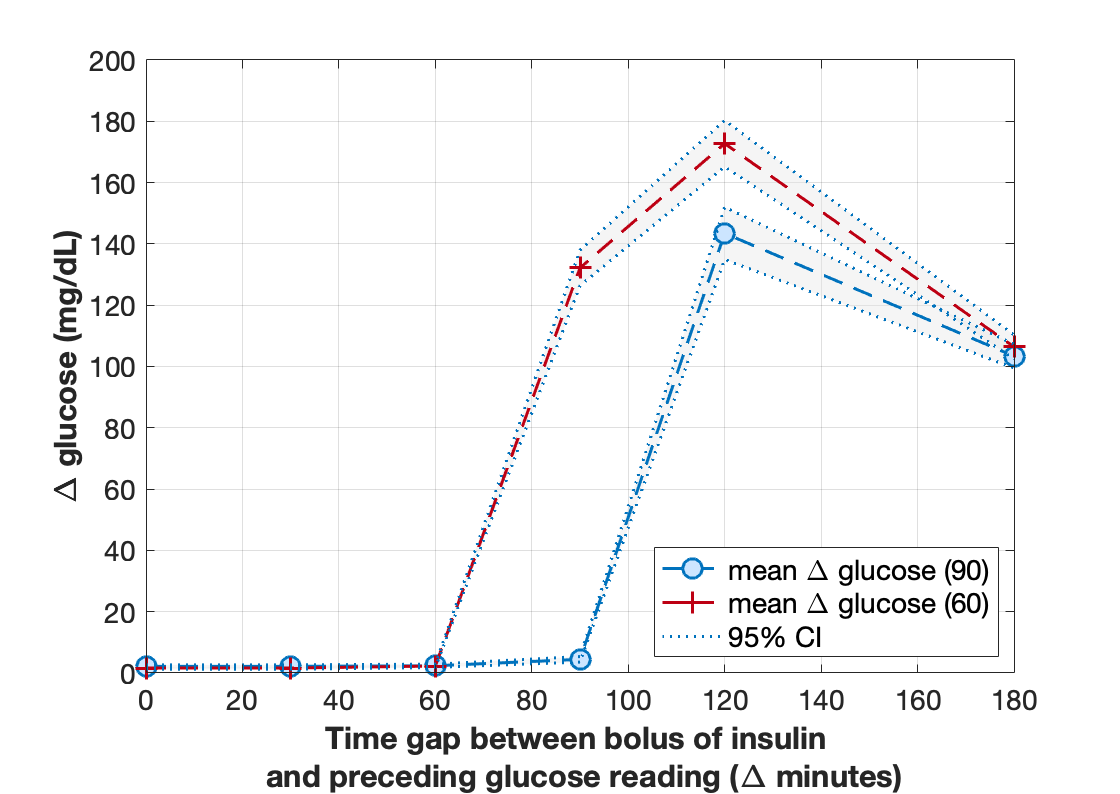

CIplot = horzcat(CIdata(1:3,1),CIdata(1:3,:));
CIplot2 = horzcat(CIdata2(1:3,1),CIdata2(1:3,:));
theta_plot = horzcat(0,theta_array,theta_array(end)+60);
x2 = [theta_plot, fliplr(theta_plot)];
tmp = CIplot(1:2,:)+CIplot(3,:);
tmp2 = CIplot2(1:2,:)+CIplot2(3,:);
inBetween = [tmp(1,:), fliplr(tmp(2,:))];
inBetween2 = [tmp2(1,:), fliplr(tmp2(2,:))];

figure
h = fill(x2, inBetween, [0.9 0.9 0.9]);
set(h,'facealpha',0.4)
set(h,'EdgeAlpha',0)
set(get(get(h,'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
hold on
f = fill(x2, inBetween2, [0.9 0.9 0.9]);
set(f,'facealpha',0.4)
set(f,'EdgeAlpha',0)
set(get(get(f,'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
plot(theta_plot, CIplot(3,:),'--o','MarkerSize',10,...
    'MarkerFaceColor','#CCE5FF',...
    'LineWidth',1.5,'DisplayName','mean \Delta glucose (90)',...
    "Color",'#0072BD')
plot(theta_plot, CIplot2(3,:),'--+','MarkerSize',10,...
    'MarkerFaceColor','#e38fa3',...
    'LineWidth',1.5,'DisplayName','mean \Delta glucose (60)',...
    "Color",'#bd0013')
g = plot(theta_plot, CIplot(1:2,:)+CIplot(3,:),':',...
    'DisplayName','95% CI','Color',[0 0.4470 0.7410],...
    'LineWidth',1.5);
set(get(get(g(2),'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
k = plot(theta_plot, CIplot2(1:2,:)+CIplot2(3,:),':',...
    'Color',[0 0.4470 0.7410],'LineWidth',1.5);
set(get(get(k(1),'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
set(get(get(k(2),'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
hold off
grid
xlabel(['Time gap between bolus of insulin ',newline,' and preceding glucose reading (\Delta minutes)'],"FontSize",16, "FontWeight","bold")
ylabel('\Delta glucose (mg/dL)', 'FontSize',16, "FontWeight","bold")
legend('FontSize', 14,'Location','southeast')
ax = gca;
ax.FontSize = 14;
fig = gcf;
fig.Units = "centimeters";
fig.Position(4) = 14;